clear all; close all;

# Example: Parabolic Launch in the Moon (Free Particle Gravity 2D)

To develop a Kalman filter to track of a particle in a parabolic launch at the moon (no atmosphere, $g=1.622\frac{m}{s^2}$).

The GPS sensor that can be used to measure the particle position have an error of $\pm 1 m$.

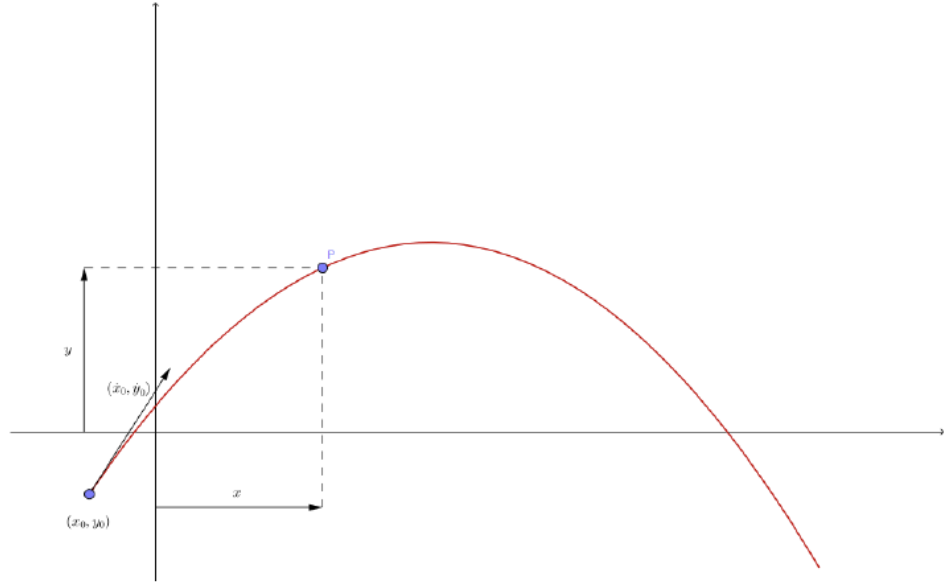

Determine transition & sensor equations, and the required Jacobians.

# Solution:

## This is the first part of the solution: Determine model and sensor equations, and export the required functions for simulation and Kalman filtering.

The derivative w.r.t. time of the state, $\dot{\mathbf{x}}(\mathbf{x},\mathbf{u},t)$ It is used to simulate the "true state" $\mathbf{x}^{tr}$.

$\dot{\mathbf{x}}(\mathbf{x},\mathbf{u},t)$ is used to define the discretized model, $\mathbf{x}_{k+1}=\mathbf{f}(\mathbf{x}_{k},\mathbf{u}_k,t_0+k~\Delta t)$ used in the Kalman filter.

$\mathbf{h}$, $\mathbf{z}_{k+1}=\mathbf{h}(\mathbf{x}_{k+1},\mathbf{u}_{k+1},t_0+(k+1)~\Delta t)$, is used to define the "true mesurements" in terms of the "true state" that is contamined with noise to generate noisy measurements.

$\mathbf{f}$ and $\mathbf{h}$ and its Jacobians w.r.t. state, $\mathbf{x}$, and input, $\mathbf{u}$, $\mathbf{f}_\mathbf{x}$, $\mathbf{f}_\mathbf{{u}$, $\mathbf{h}_\mathbf{x}$, $\mathbf{h}_\mathbf{{u}$, must be exported.

***NOTE:**** Even if the system in this example is linear we recover the linear components of the system from the general functions ( *$\mathbf{f}$* and *$\mathbf{h}$*) used in the quasilinerar version of the Kalman filter (Extendend Kalman filter) using this perspective there is no difference between Kalman and Extendend Kalman filter implementation and reasoning.*

## Parameters

syms t x dx ddx y dy ddy m g Delta_t real
param=[m, g, Delta_t]';

Generalized coordinate, velocity and acceleration vectors:

$\mathbf{q}=\left[\begin{array}{c}
x\\
y
\end{array}\right]$,$\dot{\mathbf{q}}=\left[\begin{array}{c}
\dot{x}\\
\dot{y}
\end{array}\right]$and $\ddot{\mathbf{q}}=\left[\begin{array}{c}
\ddot{x}\\
\ddot{y}
\end{array}\right]$

q=[x,y]';
dq=[dx,dy]';
ddq=[ddx,ddy]';

Forzes acting on the particle. Inertia & gravity:

$\mathbf{f}^{I}=-m ~\mathbf{a}_{moon}^P=-m ~(\ddot{x}~\mathbf{e}_x+\ddot{y}~\mathbf{e}_y)$, $\mathbf{f}^{g}=-m~g~\mathbf{e}_y$

Particle velocity:


$$\mathbf{v}^P=x~\mathbf{e}_x+y~\mathbf{e}_y$$


Virtual power equations:


$$(\mathbf{f}^{I}+\mathbf{f}^{g}) \cdot \frac{\partial~\mathbf{v}^P}{\partial~ \dot{\mathbf{q}}}=\mathbf{0}$$


iF=-m*[ddx,ddy,0]'; %xyz
gF=[0,-m*g,0]';     %xyz
V_P=[dx,dy,0]';     %xyz

Dyn_eq=-((iF+gF)'*jacobian(V_P,dq))'; Dyn_eq=simplify(Dyn_eq);

Virtual power dynamic equations structure


$$\mathbf{M}_{\dot{\mathbf{q}}\dot{\mathbf{q}}}~\ddot{\mathbf{q}}-{\mathbf{\delta}}_{\dot{\mathbf{q}}}=\mathbf{0}$$


M_qq=jacobian(Dyn_eq,ddq); M_qq=simplify(M_qq);
delta_q=-subs(Dyn_eq,ddq,sym(0)*ddq); delta_q=simplify(delta_q);

Therefore $\ddot{\mathbf{q}}(\mathbf{x},\mathbf{u},t)=\mathbf{M}_{\dot{\mathbf{q}}\dot{\mathbf{q}}} ^{-1}~\mathbf{\delta}_{\dot{\mathbf{q}}}$

ddq_func=inv(M_qq)*delta_q; ddq_func=simplify(ddq_func)

 
ddq_func =
 
 0
-g
 


To write the differential equation into first order form, the state space vector is defined as $\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\  \dot{\mathbf{q}}\end{array} \right]$.

x_=[q;dq];

$\mathbf{u}$ is not defined so its empty.

u=sym(zeros(0,0));


$$\dot{\mathbf{x}}(\mathbf{x},t)=\left[\begin{array}{c} \dot{\mathbf{q}} \\ \ddot{\mathbf{q}}(\mathbf{q},\dot{\mathbf{q}},t)\end{array}\right]$$


dstate=[dq;ddq_func]; dstate=simplify(dstate)

 
dstate =
 
dx
dy
 0
-g
 


$\dot{\mathbf{x}}_{\mathbf{x}}(\mathbf{x},t)=\frac{\partial~\dot{\mathbf{x}}(\mathbf{x},t)}{\partial ~\mathbf{x}}$, can be usefull if using exponential integration discretization.

dstate_x=jacobian(dstate,x_)

 
dstate_x =
 
[0, 0, 1, 0]
[0, 0, 0, 1]
[0, 0, 0, 0]
[0, 0, 0, 0]
 


We discretize the differential equation for the state vector, using the trivial Euler dicretization scheme, in order to obtain the discrete state transition function.


$$\mathbf{x}_{k+1}=\mathbf{x}_k+\dot{\mathbf{x}}_\mathbf{x}(\mathbf{x}_k,t)~\Delta t$$


f=x_+dstate*Delta_t; f=simplify(f) %x_k+1=f(x_k)

 
f =
 
x + Delta_t*dx
y + Delta_t*dy
            dx
dy - Delta_t*g
 


f_x=jacobian(f,x_); f_x=simplify(f_x)

 
f_x =
 
[1, 0, Delta_t,       0]
[0, 1,       0, Delta_t]
[0, 0,       1,       0]
[0, 0,       0,       1]
 


f_u=jacobian(f,u); f_u=simplify(f_u)

 
f_u =
 
Empty sym: 4-by-0
 


Position sensors in x and y axes, imply a meassurement function

h=[x
   y]; h=simplify(h)

 
h =
 
x
y
 



h_x=jacobian(h,x_); h_x=simplify(h_x)

 
h_x =
 
[1, 0, 0, 0]
[0, 1, 0, 0]
 



h_u=jacobian(h,u); h_u=simplify(h_u)

 
h_u =
 
Empty sym: 2-by-0
 


matlabFunction(f,'file','f','vars',{x_ u t param});

matlabFunction(f_x,'file','f_x','vars',{x_ u t param});

matlabFunction(f_u,'file','f_u','vars',{x_ u t param});

matlabFunction(h,'file','h','vars',{x_ u t param});

matlabFunction(h_x,'file','h_x','vars',{x_ u t param});

matlabFunction(h_u,'file','h_u','vars',{x_ u t param});

matlabFunction(dstate,'file','dstate','vars',{x_ u t param});

matlabFunction(dstate_x,'file','dstate_x','vars',{x_ u t param});